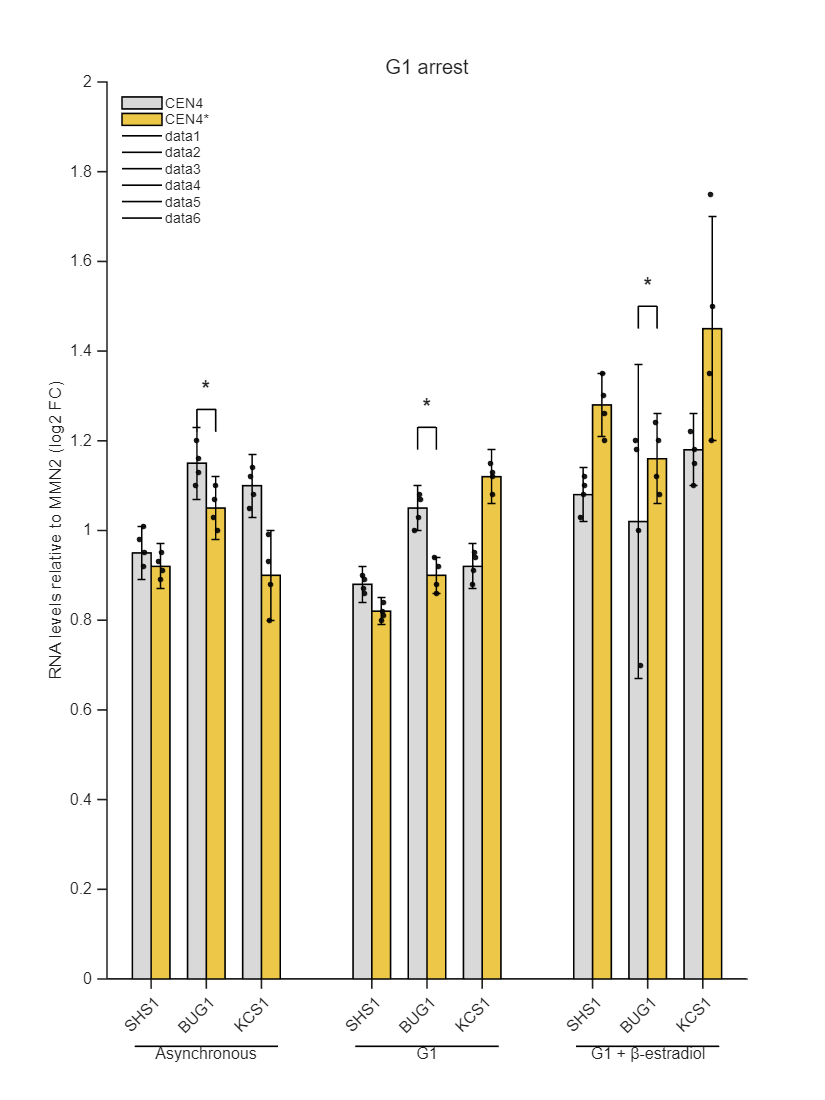

clc; clear; close all;

%% ===================== data =====================
% 9 categories:3 conditions x 3 genes
labels = {'SHS1','BUG1','KCS1','SHS1','BUG1','KCS1','SHS1','BUG1','KCS1'};

% Two group means(Example data, replace with your own)
y_gray = [0.95 1.15 1.10 0.88 1.05 0.92 1.08 1.02 1.18];
y_yel  = [0.92 1.05 0.90 0.82 0.90 1.12 1.28 1.16 1.45];

% Error(Example)
err_gray = [0.06 0.08 0.07 0.04 0.05 0.05 0.06 0.35 0.08];
err_yel  = [0.05 0.07 0.10 0.03 0.04 0.06 0.07 0.10 0.25];

% Raw replicate data for each bar(Example)
% Each cell corresponds to scatter points on one bar
raw_gray = {
    [0.92 0.98 1.01 0.95], ...
    [1.10 1.20 1.16 1.13], ...
    [1.05 1.12 1.08 1.14], ...
    [0.86 0.90 0.89 0.87], ...
    [1.00 1.08 1.03 1.07], ...
    [0.88 0.94 0.91 0.95], ...
    [1.03 1.08 1.12 1.10], ...
    [0.70 1.00 1.20 1.18], ...
    [1.10 1.15 1.22 1.18]
};

raw_yel = {
    [0.89 0.91 0.95 0.93], ...
    [1.00 1.07 1.10 1.03], ...
    [0.80 0.88 0.93 0.99], ...
    [0.80 0.82 0.84 0.81], ...
    [0.86 0.88 0.92 0.94], ...
    [1.08 1.12 1.15 1.13], ...
    [1.20 1.26 1.30 1.35], ...
    [1.08 1.12 1.20 1.24], ...
    [1.20 1.35 1.50 1.75]
};

%% ===================== Position settings =====================
% Manually set group centers, Leave gaps between major groups
x = [1 2 3  5 6 7  9 10 11];
bw = 0.34;   % Bar width

x_gray = x - bw/2;
x_yel  = x + bw/2;

%% ===================== Plot =====================
figure('Color','w','Position',[100 100 900 1200]);
ax = axes;
hold(ax,'on');

% Grouped bars
b1 = bar(x_gray, y_gray, bw, ...
    'FaceColor', [0.85 0.85 0.85], ...
    'EdgeColor', 'k', ...
    'LineWidth', 1.2);

b2 = bar(x_yel, y_yel, bw, ...
    'FaceColor', [0.93 0.78 0.28], ...
    'EdgeColor', 'k', ...
    'LineWidth', 1.2);

%% ===================== Error bars =====================
errorbar(x_gray, y_gray, err_gray, 'k', ...
    'LineStyle', 'none', 'LineWidth', 1.1, 'CapSize', 6);

errorbar(x_yel, y_yel, err_yel, 'k', ...
    'LineStyle', 'none', 'LineWidth', 1.1, 'CapSize', 6);

%% ===================== Overlay scatter points =====================
jit = 0.05;   % Jitter amplitude

for i = 1:numel(x)
    % Gray-bar scatter
    xx1 = x_gray(i) + (rand(size(raw_gray{i})) - 0.5) * 2 * jit;
    scatter(xx1, raw_gray{i}, 18, 'k', 'filled', ...
        'MarkerFaceAlpha', 0.9, 'MarkerEdgeAlpha', 0.9);

    % Yellow-bar scatter
    xx2 = x_yel(i) + (rand(size(raw_yel{i})) - 0.5) * 2 * jit;
    scatter(xx2, raw_yel{i}, 18, 'k', 'filled', ...
        'MarkerFaceAlpha', 0.9, 'MarkerEdgeAlpha', 0.9);
end

%% ===================== Axis formatting =====================
xlim([0.2 11.8]);
ylim([0 2.0]);

set(gca, ...
    'XTick', x, ...
    'XTickLabel', labels, ...
    'XTickLabelRotation', 45, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'off', ...
    'TickDir', 'out');

ylabel('RNA levels relative to MMN2 (log2 FC)', 'FontSize', 13);
title('G1 arrest', 'FontSize', 15, 'FontWeight', 'normal');

legend([b1 b2], {'CEN4', 'CEN4*'}, ...
    'Location', 'northwest', 'Box', 'off');

%% ===================== Group labels and underline =====================
% Draw group lines and labels under the axes
y_group = -0.15;   % Horizontal-line position(relative to current y axis, Required clip Close)
text_y  = -0.15;

draw_group(ax, [0.7 3.3], y_group, 'Asynchronous', text_y);
draw_group(ax, [4.7 7.3], y_group, 'G1', text_y);
draw_group(ax, [8.7 11.3], y_group, 'G1 + β-estradiol', text_y);

%% ===================== Significance bracket =====================
% example:at index2、5、8add significance for group
add_sig(ax, x_gray(2), x_yel(2), 1.22, '*');
add_sig(ax, x_gray(5), x_yel(5), 1.18, '*');
add_sig(ax, x_gray(8), x_yel(8), 1.45, '*');

%% make bottom labels visible
set(gca, 'Clipping', 'off');


%% ===================== Subfunction =====================
function add_sig(ax, x1, x2, y, txt)
    h = 0.05; % Bracket height
    plot(ax, [x1 x1 x2 x2], [y y+h y+h y], 'k', 'LineWidth', 1.2, 'Clipping', 'off');
    text(ax, mean([x1 x2]), y+h+0.02, txt, ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom', ...
        'FontSize', 16, 'FontWeight', 'bold', ...
        'Clipping', 'off');
end

function draw_group(ax, xrange, yline, txt, ytxt)
    plot(ax, xrange, [yline yline], 'k', 'LineWidth', 1.2, 'Clipping', 'off');
    text(ax, mean(xrange), ytxt, txt, ...
        'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'top', ...
        'FontSize', 12, 'Clipping', 'off');
end
